# LKA RL Training

clear;
close all;
bdclose('all');
addpath("/home/momentumlab/Documents/git/AI-CPS-Ensemble/LKA/model");

## Environment Setup

m = 1575;   % total vehicle mass (kg)
Iz = 2875;  % yaw moment of inertia (mNs^2)
lf = 1.2;   % longitudinal distance from center of gravity to front tires (m)
lr = 1.6;   % longitudinal distance from center of gravity to rear tires (m)
Cf = 19000; % cornering stiffness of front tires (N/rad)
Cr = 33000; % cornering stiffness of rear tires (N/rad)

Vx = 15;    % longitudinal velocity (m/s)

Ts = 0.1;   % sample time
T = 15;     % simulation time

u_min = -0.5;   % maximum steering angle
u_max = 0.5;    % minimum steering angle

line_width = 3.7;   % highway lane width
avg_car_width = 2;  % average car width 
max_late_dev = (line_width-avg_car_width)/2-0.1;
max_rel_yaw_ang = 0.261799; % lateral deviation tolerence
lat_terminate_error = 1.5;

rho = 0.001;        % curvature of the road
e1_initial = 0.2;   % initial lateral deviation
e2_initial = 0.1;   % initial yaw angle

time = 0:Ts:T;
md = getCurvature(Vx,time); % previewed curvature

mdl = 'LKA_RL_training';       % simulink model
agentblk = [mdl '/RL Agent'];

## DRL Obs/Act configuration

Creating an environment model includes action, obervation

**Observation**: 

- Leteral deviation

- Integral of leteral deviation

- Relative yaw angle

- Integral of relative yaw angle

- Derivative of lateral deviation

- Derivative of relative yaw angle

**Action**: Ego car steering anfle, [-0.5, 0.5]

obsInfo = rlNumericSpec([6 1],...
    'LowerLimit', [-inf, -inf, -inf, -inf, -inf,-inf]',...
    'UpperLimit', [inf, inf, inf, inf, inf, inf]');
obIsnfo.Name = 'observations';
obsInfo.Description = 'lateral deviation and yaw angle';
numObservations = obsInfo.Dimension(1);

% action
actInfo = rlNumericSpec([1 1]);
actInfo.LowerLimit = u_min;
actInfo.UpperLimit = u_max;
actInfo.Name = 'steering angle';
numActions = actInfo.Dimension(1);

% Build the environment interface object.
env = rlSimulinkEnv(mdl,agentblk,obsInfo,actInfo);

% Set a custom reset function that randomizes the reference values for the model.
env.ResetFcn = @(in)localResetFcn(in);

% Fix the random generator seed for reproducibility
% rng(0);

% x = linspace(0,1,300);
% y  = zeros(300,1);
% actionThreshold = 0.5;
% 
% for i = 1:length(x)
% %     if x(i)<=actionThreshold
% %         y(i) = tanh(8*abs(max_rel_yaw_ang-x(i)));
% %     else
% %         y(i) = -tanh(9*abs(max_rel_yaw_ang-x(i)));
% %     end
%     y(i) = -x(i)^2;
% end
% 
% figure;
% plot(x,y);

## DRL Agent Configuration

Create a network to be used as underlying critic approximator

statePath = [
    featureInputLayer(numObservations,'Normalization','none','Name','observation')
    fullyConnectedLayer(64,'Name','CriticStateFC1')
    reluLayer('Name','CriticRelu1')
    fullyConnectedLayer(128,'Name','CriticStateFC2')];

actionPath = [
    featureInputLayer(1,'Normalization','none','Name','action')
    fullyConnectedLayer(128,'Name','CriticActionFC2')];

commonPath = [
    additionLayer(2,'Name','add')
    reluLayer('Name','CriticCommonRelu1')
    fullyConnectedLayer(256,'Name','CriticCommonFC1')
    reluLayer('Name','CriticCommonRelu2')
    fullyConnectedLayer(64,'Name','CriticCommonFC2')
    reluLayer('Name','CriticCommonRelu3')
    fullyConnectedLayer(1,'Name','CriticOutput')];

criticNetwork = layerGraph(statePath);
criticNetwork = addLayers(criticNetwork,actionPath);
criticNetwork = addLayers(criticNetwork,commonPath);
criticNetwork = connectLayers(criticNetwork,'CriticStateFC2','add/in1');
criticNetwork = connectLayers(criticNetwork,'CriticActionFC2','add/in2');

% convert the network to a dlnetwork object
criticNetwork = dlnetwork(criticNetwork);

% create the critic based on the network approximator
critic = rlQValueFunction(criticNetwork,obsInfo,actInfo,'UseDevice','cpu');

% create a network to be used as underlying actor approximator
actorNetwork = [
    featureInputLayer(numObservations,'Normalization','none','Name','observation')
    fullyConnectedLayer(64,'Name','ActorFC1')
    reluLayer('Name','ActorRelu1')
    fullyConnectedLayer(128,'Name','ActorFC2')
    reluLayer('Name','ActorRelu2')
    fullyConnectedLayer(256,'Name','ActorFC3')
    reluLayer('Name','ActorRelu3')
    fullyConnectedLayer(64,'Name','ActorFC4')
    reluLayer('Name','ActorRelu4')
    fullyConnectedLayer(1,'Name','ActorFC5')
    tanhLayer('Name','ActorTanh1')
    scalingLayer('Name','ActorScaling','Scale',actInfo.UpperLimit, 'Bias',0)];

actor = rlContinuousDeterministicActor(actorNetwork,obsInfo,actInfo,'UseDevice','cpu');

DDPG agent options: actor, critic optimizer

**Noise model:**

- It is common to set `StandardDeviation*sqrt(Ts)` to a value between 1% and 10% of your action rang.

- To increase exploration, you can reduce the `StandardDeviationDecayRate`.


% Optimization options for actors and critics
myCriticOpts=rlOptimizerOptions(...
    'LearnRate',1e-3,...
    'GradientThreshold',1,...
    'GradientThresholdMethod',"l2norm",...
    'L2RegularizationFactor', 1e-4,...
    'Optimizer',"adam");

myActorOpts=rlOptimizerOptions(...
    'LearnRate',1e-4,...
    'GradientThreshold',1,...
    'GradientThresholdMethod',"l2norm",...
    'L2RegularizationFactor', 1e-4,...
    'Optimizer',"adam");

% Options for DDPG agent
agentOptions = rlDDPGAgentOptions(...
    'CriticOptimizerOptions', myCriticOpts,...
    'ActorOptimizerOptions',myActorOpts,...
    'SampleTime',Ts,...
    'TargetSmoothFactor',1e-3,...
    'TargetUpdateFrequency',1,...
    'ExperienceBufferLength',1e6,...
    'NumStepsToLookAhead',10,...
    'MiniBatchSize',128,...
    'DiscountFactor',0.99);

agentOptions.NoiseOptions.StandardDeviation = 0.05*(1)/sqrt(Ts);
agentOptions.NoiseOptions.StandardDeviationDecayRate = 1e-5;

% agent creation
agent = rlDDPGAgent(actor,critic,agentOptions);

## **Training Configurations**

Change the weights distribution among subsitutional rewards

maxepisodes = 8000; 
maxsteps = ceil(T/Ts);
window_length = 20;

% change reward weights distribution
rewardWeights = [0.2, 0.8, 0.05];

trainOpts = rlTrainingOptions(...
    'MaxEpisodes', maxepisodes, ...
    'MaxStepsPerEpisode', maxsteps, ...
    'ScoreAveragingWindowLength',window_length, ...
    'StopTrainingCriteria','AverageReward',...
    'StopTrainingValue', sum(rewardWeights)*maxsteps*0.95,...
    'Verbose', false,...
    'Plots','training-progress',...
    'UseParallel',false);

doTraining = true;

if doTraining
    % Train the agent.
    isTerminate = true;
    trainingStats = train(agent,env,trainOpts);
else
%     agent = load('preTrainedAgent.mat');
%     agent = agent.agent;
end

## Save trained agent 

Save DRL agent with training configurations, agent configurations and training progress info

isSave = true;

if isSave
    dateOfTrain = date;
    agentName = ['LKA-DDPG-', dateOfTrain(1:end-5)];
    agentName = agentName+...
        "-"+string(rewardWeights(1))+...
        "-"+string(rewardWeights(2))+...
        "-"+string(rewardWeights(3));

    saveAgent = struct('agentName', agentName, ...
                 'agent', agent, ...
                 'rewardWeights', rewardWeights, ...
                 'agentOptions', agentOptions, ...
                 'criticNetwork', criticNetwork, ...
                 'actorNetwork', actorNetwork, ...
                 'trainOpts', trainOpts);

    path = "/home/momentumlab/Documents/git/AI-CPS-Ensemble/LKA/DRL_training/trained_agent/";
    save(path+agentName+'.mat', "saveAgent");
    disp(agentName + ' saved')
end

LKA-DDPG-17-Jun-0.2-0.8-0.05 saved


## Simulation & plotting

control_switch = 0; simulation option

simOpts = rlSimulationOptions('MaxSteps',maxsteps,'StopOnError','on');
% get results
experiences = sim(env,agent,simOpts);
totalReward = sum(experiences.Reward);

% extract signals from simulation results
time = experiences.SimulationInfo.tout;
steps = size(time);
steps = steps(1);
lateral_deviation = experiences.SimulationInfo.logsout.getElement('lateral_deviation').Values.Data;
relative_yaw_angle =  experiences.SimulationInfo.logsout.getElement('relative_yaw_angle').Values.Data;
RL_steer_angle =  experiences.SimulationInfo.logsout.getElement('RL_steer_angle').Values.Data;
RL_steer_angle = reshape(RL_steer_angle, [steps,1]);
% MPC_steering_angle =  experiences.SimulationInfo.logsout.getElement('MPC_steering_angle').Values.Data;
velocity =  experiences.SimulationInfo.logsout.getElement('Vx').Values.Data;
velocity = velocity(1);

## Simulation & Plotting

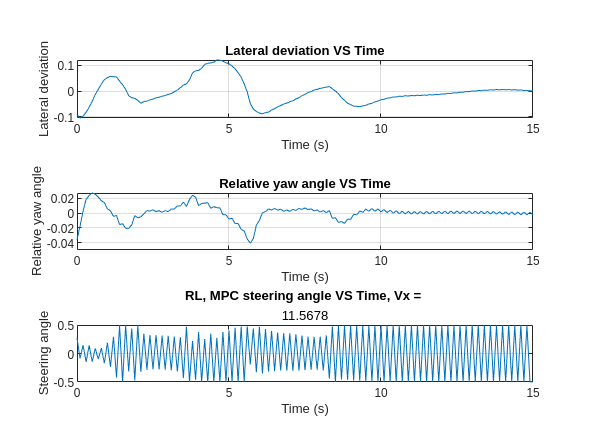

figure(1);
subplot(3,1,1)
plot(time,lateral_deviation)
title('Lateral deviation VS Time')
xlabel('Time (s)') 
ylabel('Lateral deviation') 
grid on

subplot(3,1,2)
plot(time,relative_yaw_angle)
title('Relative yaw angle VS Time')
xlabel('Time (s)') 
ylabel('Relative yaw angle') 
grid on

subplot(3,1,3)
plot(time,RL_steer_angle)
title('RL, MPC steering angle VS Time, Vx = ',velocity)
% legend('RL', 'MPC')
xlabel('Time (s)') 
ylabel('Steering angle') 
grid on

## Training progress info

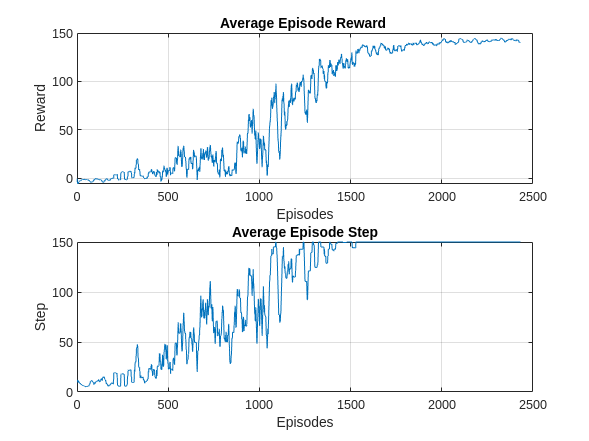

episodes = trainingStats.EpisodeIndex;
episode_reward = trainingStats.EpisodeReward;
episode_step = trainingStats.EpisodeSteps;
episode_avg_reward = trainingStats.AverageReward;
episode_avg_step = trainingStats.AverageSteps;

figure(2);
subplot(2,1,1)
plot(episodes,episode_avg_reward)
title('Average Episode Reward ')
xlabel('Episodes') 
ylabel('Reward') 
grid on

subplot(2,1,2)
plot(episodes,episode_avg_step)
title('Average Episode Step')
xlabel('Episodes') 
ylabel('Step') 
grid on

## Reset function

Generate random initial conditions:

- Initial lateral deviation: [-0.5, 0.5]

- Initial relative yaw angle: [-0.1, 0.1]

- Initial velocity: [10, 25]

function in = localResetFcn(in)
    % reset
    in = setVariable(in,'e1_initial', 0.5*(-1+2*rand)); % random value for lateral deviation
    in = setVariable(in,'e2_initial', 0.1*(-1+2*rand)); % random value for relative yaw angle
    in = setVariable(in,'Vx', 10+15*rand);              % random value for longitudinal velocity
end